plt1 = csvread("Exp3_Plot1_Large_Amplitude.csv");
startpoint = 4700;
endpoint = 6500;
time=plt1(startpoint:endpoint,1,:);
ch1=plt1(startpoint:endpoint,2,:);
ch2=plt1(startpoint:endpoint,3,:);
time = time + 0;

% Plot input and output waveforms
figure;
%semilogy(time,ch2-min(ch2),'b')
slew_rate_up = (3.43315 - 0.525248)/(0.0125058 - 0.010037);
slew_rate_down = (3.34492 - 0.940662)/(0.0151495  - 0.0169058);
xup = [0.0125058, 0.010037];
xdown = [0.0151495, 0.0169058];
up_line = slew_rate_up*xup - 11.27;
down_line = slew_rate_down*xdown + 24.05;


plot(time,ch1); hold on
plot(time,ch2);
plot(xup,up_line);
plot(xdown,down_line);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Input and Output Scopetraces with extracted slew rates');
legend('Input (ch1)', 'Output (ch2)','Up-going slew rate: 1177.860499','Down-going slew rate: -1368.933553');
ylim([0,6])
grid on;
fprintf('Up-going slewrate: %f\n', slew_rate_up)

Up-going slewrate: 1177.860499


fprintf('Down-going time constant: %f\n', slew_rate_down)

Down-going time constant: -1368.933553


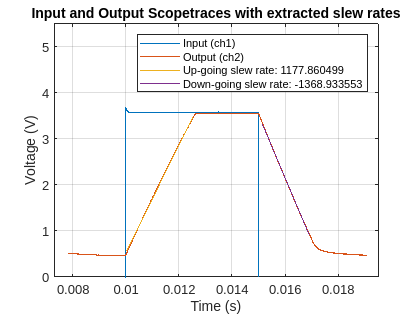

print("-depsc","experiment3_2.eps")

xlim([0.0073 0.0195])
ylim([-0.00 5.50])

function [first, last, mmax, bmax, Nmax]=linefit(x, y, epsilon)

first=0;
last=0;
mmax=0;
bmax=0;
Nmax=0;

i=1;
while i<length(x),
    R2=1;
    N=1;
    sumX=x(i);
    sumX2=x(i)*x(i);
    sumY=y(i);
    sumY2=y(i)*y(i);
    sumXY=x(i)*y(i);
    j=i;
    while (j<length(x)) & (R2>1-epsilon),
        j=j+1;
        N=N+1;
        sumX=sumX+x(j);
        sumX2=sumX2+x(j)*x(j);
        sumY=sumY+y(j);
        sumY2=sumY2+y(j)*y(j);
        sumXY=sumXY+x(j)*y(j);
        SXX=sumX2-sumX*sumX/N;
        SYY=sumY2-sumY*sumY/N;
        SXY=sumXY-sumX*sumY/N;
        m=SXY/SXX;
        b=(sumY-m*sumX)/N;
        R2=SXY*SXY/(SXX*SYY);
    end
    if ((N>10) & (abs(m)>abs(mmax))),
        first=i;
        last=j;
        mmax=m;
        bmax=b;
        Nmax=N;
    end
    i=j;
end
end
